qtdCols = 5;                        %Define quantas colunas irei utilizar levando em consedaração o arquivo importado%

#### Importando os dados para o programa

data = readmatrix('C:\Users\gabri\OneDrive\Área de Trabalho\ia\matLab\bnb.csv');
data = data(4:1090, 2:17);          %Removendo coluna de datas%

#### Definindo dados de atuação (de acordo com a tabela recebida)

x = data(:, 1:qtdCols);             %Rows and columns (definindo variaveis de entrada)%
y = data(:,16);                     %Rows and Columns (definindo variavel de previsão)%
m = length(y);                      %Pega a quantidade de dados que temos para resultados%

#### Exibe a saída e a normaliza com uma função log

Como o histogram gerado pela saída Y teve seus dados concentrados em somente um ponto, fez-se a normalização dos dados atráves da função logarítmica (de Y acrescido de 1 para evitar log de 0) para que eles ficassem esparsos sem perdere as caracteristicas do sistema estudado

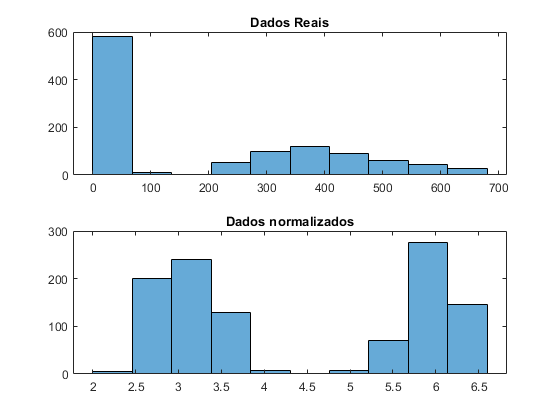

y2 = log(1+y);                      %Normaliza a saída desejada%
figure(1);
subplot(2,1,1);
histogram(y,10);                    %Exibe um histograma com o range de valores possiveis e seu suposto peso%
title("Dados Reais");
subplot(2,1,2);
histogram(y2,10);
title("Dados normalizados");

#### Normalizando os dados de entrada e plotando

É feita uma comparação gráfica dos dados não normalizados e dos dados normalizados para que possamos ver a diferença na amostragem dos dados

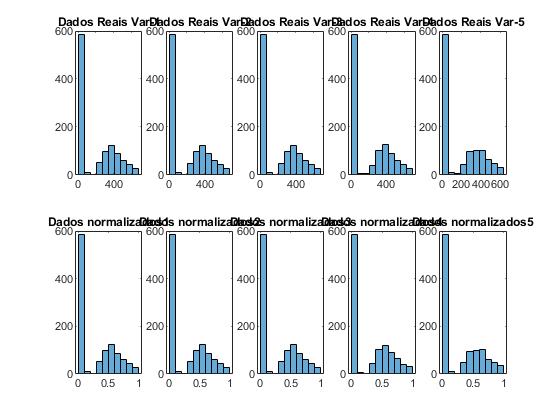

for i = 1:1:qtdCols                                                 %Normaliza as entradas%
    x2(:,i) = (x(:,i)-min(x(:,i)))/(max(x(:,i)) - min(x(:,i)));
end
figure(2);
for i = 1:1:qtdCols
    subplot(2,qtdCols,i);
    histogram(x(:,i),10);                    %Exibe um histograma com o range de valores possiveis e seu suposto peso%
    title(strcat('Dados Reais Var-',num2str(i)));
    
    subplot(2,qtdCols,qtdCols+i);
    histogram(x2(:,i),10);
    title(strcat('Dados normalizados',num2str(i)));
end

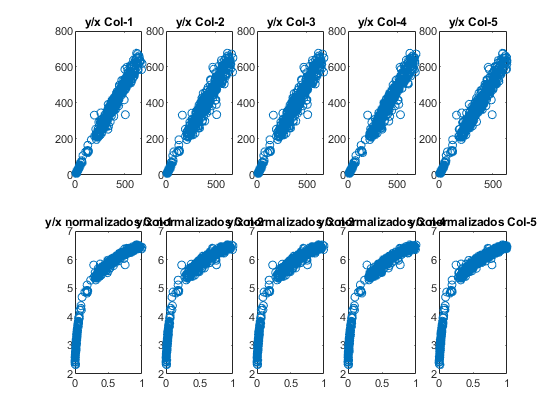


%Plota varios gráficos das relações das variaveis escolhidas com a saída desejada (todas normalizadas)%
for i = 1:1:qtdCols
    figure(3);
    subplot(2,qtdCols,i);            %Define quantos grids de plot e qual a posição do plot atual no grid 
    plot(x(:,i),y, 'o');
    title(strcat('y/x Col-', num2str(i)));
    
    subplot(2,qtdCols,qtdCols+i);            %Define quantos grids de plot e qual a posição do plot atual no grid 
    plot(x2(:,i),y2, 'o');
    title(strcat('y/x normalizados Col-', num2str(i)));
end

#### Trasposição de matriz e definição de variaveis

Foi realizada a trasposta das matrizes de entrada e saída para que possam ser processadas pela função do matlab. Algumas variaveis foram declaradas para auxiliar a etapa de otimização da rede

xt = x2';                                       %Calculando a matriz transposta de entradas (pois a função de treinamento so aceita assim)%
yt = y2';                                       %Calculando a matriz transposta de saída (pois a função de treinamento so aceita assim)%

bestPercentError = 100;                         %Menor erro gerado por determinada quantidade de neurônio "bestQtdNeuron", calculado através da média ponderada%
bestQtdNeuron = 0;                              %A quantidade de neuronios que gerou o menor erro durante os teste%
maxNeurons = 60;                                %Quantidade máxima de neuronios para teste%

#### Otimizando a quantidade de neurônios na camada interna (verificando o melhor resultado de acordo a qtd)

Como a quantidade de neurônios na camada interna da rede neural é incerta, esta etapa faz um teste variando a volume de neurônios de 1 até <maxNeurons>, salvando a quantidade que tiver o melhor desempenho.

for i = 1:1:maxNeurons                                              %testando redes com 1 até <maxNeurons> neuronios na camada interna%
    
    %Treinando a rede neural%
    hiddenLayerSize = i;                                            %Número de neurônios da camada oculta%
    net = fitnet(hiddenLayerSize);                                  %Cria a rede neural com <i> neurons na camada interna <qtdCols> na camada de entrada e 1 na camada de saída%

    %Define a porcentagem de dados utilizados para as etapas de (Treino, validação e test)%
    net.divideParam.trainRatio = 70/100;                            %Porcentagem de treinamento%
    net.divideParam.valRatio   = 15/100;                            %Porcentagem de validação%
    net.divideParam.testRatio  = 15/100;                            %Porcentagem de teste%

    %Treinando o modelo%
    [net, tr] = train(net, xt, yt);                                 %tr nos da informações sobre o desempenho da rede no treinamento%

    %Verificando a performance da rede neural%
    ytrain = exp(net(xt(:,tr.trainInd)))-1;                        %Pega o valor previsto pela rede neural para o conjunto de Treino%
    ytrainTrue = exp(yt(tr.trainInd))-1;                           %Pega o valor verdadeiro (esperado) do conjunto de Treino%
    percentTrainError(i) = sqrt(mean((ytrain-ytrainTrue).^2));     %Tira o erro quadrado médio%

    yVal = exp(net(xt(:,tr.valInd)))-1;                            %Pega o valor previsto pela rede neural para o conjunto de Validação%
    yValTrue = exp(yt(tr.valInd))-1;                               %Pega o valor verdadeiro (esperado) do conjunto de Validação%
    percentValidationError(i) = sqrt(mean((yVal-yValTrue).^2));    %Tira o erro quadrado médio%

    yTest = exp(net(xt(:,tr.testInd)))-1;                          %Pega o valor previsto pela rede neural para o conjunto de Teste%
    yTestTrue = exp(yt(tr.testInd))-1;                             %Pega o valor verdadeiro (esperado) do conjunto de Teste%
    percentTestError(i) = sqrt(mean((yTest-yTestTrue).^2));        %Tira o erro quadrado médio%
    
    %Seleciona o melhor desempenho gerado pela rede%
    if (2*percentTestError(i) + percentValidationError(i) + percentTrainError(i))/4 < bestPercentError
        bestPercentError = (2*percentTestError(i) + percentValidationError(i) + percentTrainError(i))/4;        %O erro calculado com uma média ponderada, tal que a etapa de Test tem peso 2%
        bestQtdNeuron = i;
    end
end

#### Plotando o gráfico que mostra a taxa de erro por qtd de neurônios

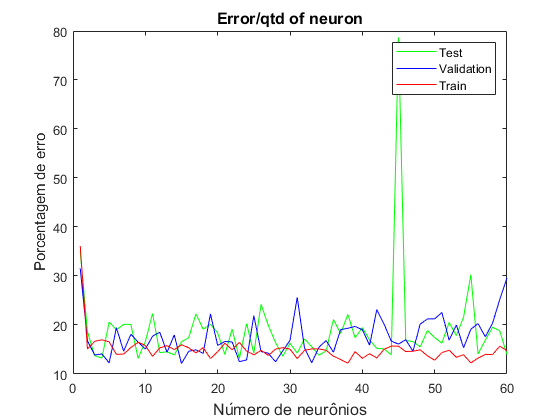

figure(4);
plot(1:maxNeurons, percentTestError,"g"); hold on;
plot(1:maxNeurons, percentValidationError,"b"); hold on;
plot(1:maxNeurons, percentTrainError,"r"); hold off;
title("Error/qtd of neuron","FontSize",12);
xlabel("Número de neurônios","FontSize",12);
ylabel("Porcentagem de erro");
legend("Test","Validation", "Train");

#### Treinando a rede neural com a melhor qtd de neurônios

%Treinando a rede neural%
hiddenLayerSize = bestQtdNeuron;                                %Número de neurônios da camada oculta%
net = fitnet(hiddenLayerSize);                                  %Cria a rede neural com <bestQtdNeuron> neurons na camada interna <qtdCols> na camada de entrada e 1 na camada de saída%

%Define a porcentagem de dados utilizados para as etapas de (Treino, validação e test)%
net.divideParam.trainRatio = 70/100;                           %Porcentagem de treinamento%
net.divideParam.valRatio   = 15/100;                           %Porcentagem de validação%
net.divideParam.testRatio  = 15/100;                           %Porcentagem de teste%

%Treinando o modelo%
[net, tr] = train(net, xt, yt);                                 %tr nos da informações sobre o desempenho da rede no treinamento%

%Verificando a performance da rede neural%
ytrain = exp(net(xt(:,tr.trainInd)))-1;                        %Pega o valor previsto pela rede neural para o conjunto de Treino%
ytrainTrue = exp(yt(tr.trainInd))-1;                           %Pega o valor verdadeiro (esperado) do conjunto de Treino%
percentTrainError = sqrt(mean((ytrain-ytrainTrue).^2));        %Tira o erro quadrado médio%

yVal = exp(net(xt(:,tr.valInd)))-1;                            %Pega o valor previsto pela rede neural para o conjunto de Validação%
yValTrue = exp(yt(tr.valInd))-1;                               %Pega o valor verdadeiro (esperado) do conjunto de Validação%
percentValidationError = sqrt(mean((yVal-yValTrue).^2));       %Tira o erro quadrado médio%

yTest = exp(net(xt(:,tr.testInd)))-1;                          %Pega o valor previsto pela rede neural para o conjunto de Teste%
yTestTrue = exp(yt(tr.testInd))-1;                             %Pega o valor verdadeiro (esperado) do conjunto de Teste%
percentTestError = sqrt(mean((yTest-yTestTrue).^2));           %Tira o erro quadrado médio%

#### Plota um gráfico da saida desejada X dados previstos

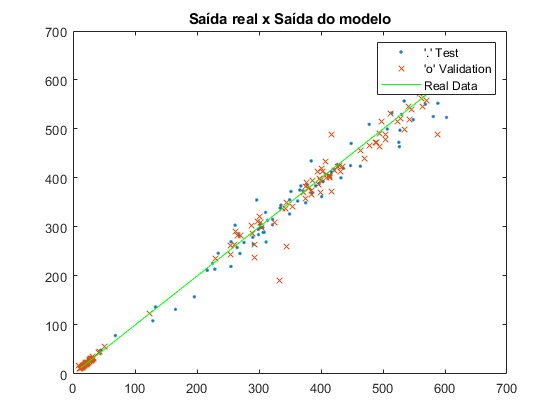

figure(5);
plot(yTestTrue, yTest,"."); hold on;
plot(yValTrue, yVal,"x"); hold on;
plot(yTestTrue, yTestTrue,"g"); hold off;
title("Saída real x Saída do modelo");
legend("'.' Test","'o' Validation", "Real Data");